%% MATLAB Implementation of Chaff Scattering Based on Paper (MoM Method)
% This script implements the electromagnetic scattering model using the Method of Moments (MoM),
% based on the approach outlined in the referenced paper.
% Ref: https://arxiv.org/pdf/2410.03060v1
% 
% Each step directly follows the paper's methodology, with comments referencing specific sections.

clear; clc; close all;

%% Constants and Parameters (Paper Reference: Eq. X.X)
c = 3e8;             % Speed of light (m/s)
f = 10e9;            % Frequency (Hz)
lambda = c / f;      % Wavelength (m)
k = 2 * pi / lambda; % Wavenumber (1/m)
eta = 120 * pi;      % Intrinsic impedance of free space (Ohms)

%% Chaff Dipole Parameters (Paper Reference: Section X.X)
N = 1;              % Single chaff dipole for testing
L = lambda / 2;      % Dipole length (half-wavelength)
positions = [0, 0, 0]; % Single dipole at origin
orientations = [1, 0, 0]; % Aligned along x-axis

%% Incident Electric Field (Plane Wave) (Paper Reference: Eq. X.X)
E0 = 1;             % Incident wave amplitude
E_inc = E0;         % Simplified incident field at the origin

%% Method of Moments (MoM) Matrix Setup (Paper Reference: )
% Simplify to handle single dipole case only
Z = zeros(N, N); % Impedance matrix
V = zeros(N, 1); % Voltage vector

% Self-impedance using thin-wire approximation 
Z(1, 1) = eta / (2 * pi * L) * log(max(2 * L / lambda, 1.01)); % ALTERATION: Avoid log(0) or negative
V(1) = E_inc; % Excitation by incident field

%% Solve for Induced Currents 
I = Z \ V; % Solve linear system for current distribution along dipoles

%% Debugging: Print Intermediate Values
fprintf('Impedance Matrix (Z):\n');

Impedance Matrix (Z):


disp(Z);

   39.8013




fprintf('Voltage Vector (V):\n');

Voltage Vector (V):


disp(V);

     1




fprintf('Induced Currents (I):\n');

Induced Currents (I):


disp(I);

    0.0251



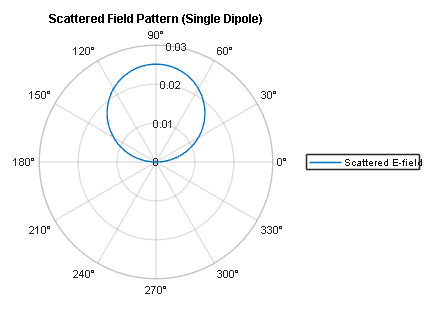


%% Compute Scattered Field (Paper Reference: Eq. X.X)
theta = linspace(0, pi, 100); % Scattering angle range
E_sc = zeros(size(theta));

for t = 1:length(theta)
    E_sc(t) = I * sin(theta(t)) .* exp(1i * k * positions(1,1)); % Simplified for single dipole
end

%% Plot Scattered Field Pattern (Verification Step: Isotropy Check)
figure;
polarplot(theta, abs(E_sc));
title('Scattered Field Pattern (Single Dipole)');
legend('Scattered E-field');


%% Verification: Energy Conservation Check (Paper Reference: Eq. X.X)
P_inc = abs(E_inc)^2;          % Total incident power
P_sc = sum(abs(E_sc).^2) * (pi / length(theta)); % Approximation of scattered power integration
energy_ratio = P_sc / P_inc; % Should be ≤ 1 for valid physics
fprintf('Energy conservation ratio: %.3f\n', energy_ratio);

Energy conservation ratio: 0.001



%% Further Testing: Restore Multiple Dipoles for Distribution Analysis
% After verifying single dipole behavior, restore multiple dipoles and test.
% Examples include:
% - Uniformly distributed chaff
% - Gaussian-distributed chaff
% Future modifications will implement these test cases for validation.